# Getting Started with MATLAB Support for BITalino Biosignal Devices

BITalino devices are ideal for prototyping and creating biomedical applications using biosignal sensors. The MATLAB Support for BITalino Biosignal Device enables you to connect and acquire biosignal data from the BITalino (r)evolution board and other BITalino (r)evolution Plugged kits.

## Setup

Switch on the BITalino and pair it with your computer over Bluetooth to connect and start reading data from the device.

## Functions

- bitalinolist - Scan nearby BITalino devices.

- bitalino - Connect to the BITalino device over Bluetooth.

- read - Acquire and read data from BITalino.

- writeDigitalPins  - Write data to turn on/off digital outputs.

## Example

This example helps you to discover available BITalino devices, connect, acquire, and plot an ECG signal from the ECG sensor available in the BITalino (r)evolution board.

Scan for the nearby BITalino device

list = bitalinolist;

Connect to a specific BITalino device by passing its name or address. You can also connect to the first available BITalino by using the bitalino function without any inputs

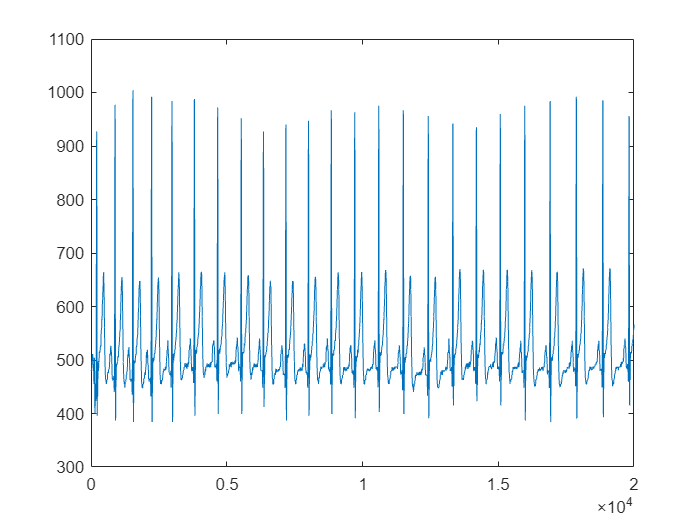

b = bitalino();

Now considering the ECG sensor is connected to the channel A2 and ready for acquiring data, read all the analog channel data from BITalino and filter out the ECG data

bioSignal = read(b,"Duration",20);
ecgSignal = bioSignal.A2;

Plot the ECG signal, which may look something like the figure below

plot(ecgSignal);

Copyright © 2023 The MathWorks, Inc.